s = tf('s')  % laplace variable

s =
 
  s
 
Continuous-time transfer function.



## Real LHP Poles

Let's consider one pole at -10. What does the frequency response look like?

wo = 10;    % break frequency
G1 = 1 / (s/wo +1)

G1 =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



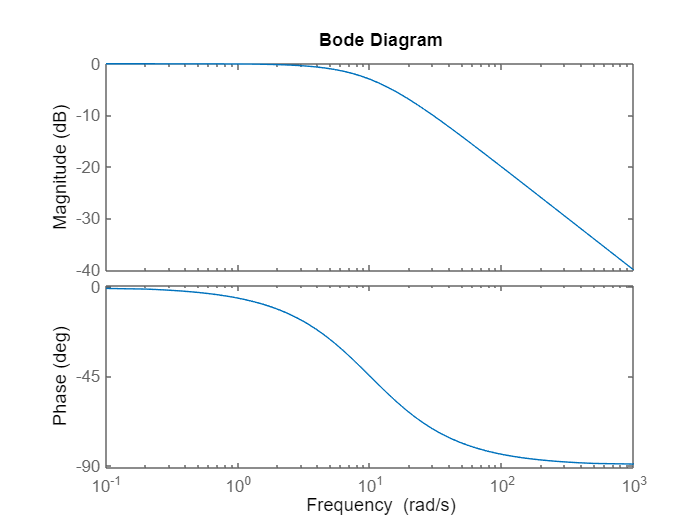

bode(G1)

Let's consider another system with a pole at -1000?

wo = 1000;    % break frequency
G2 = 1 / (s/wo +1)

G2 =
 
    1000
  --------
  s + 1000
 
Continuous-time transfer function.



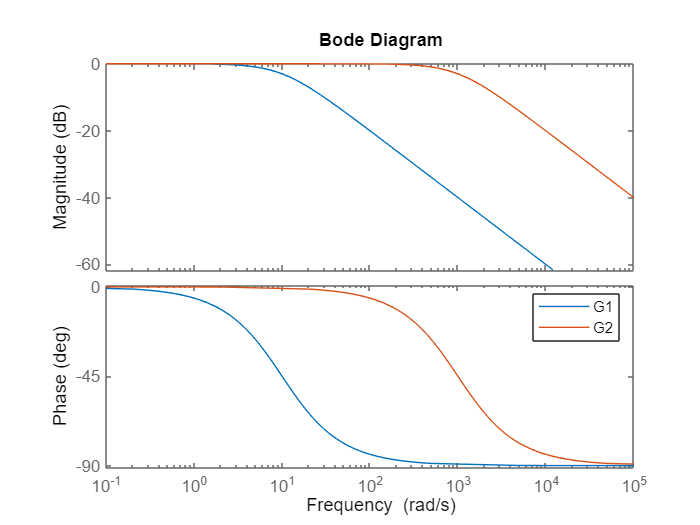

bode(G1, G2)
legend("G1", "G2")

Let's now cascade (use the output of one system as the input of another) two systems:

G12 = G1*G2

G12 =
 
         10000
  --------------------
  s^2 + 1010 s + 10000
 
Continuous-time transfer function.



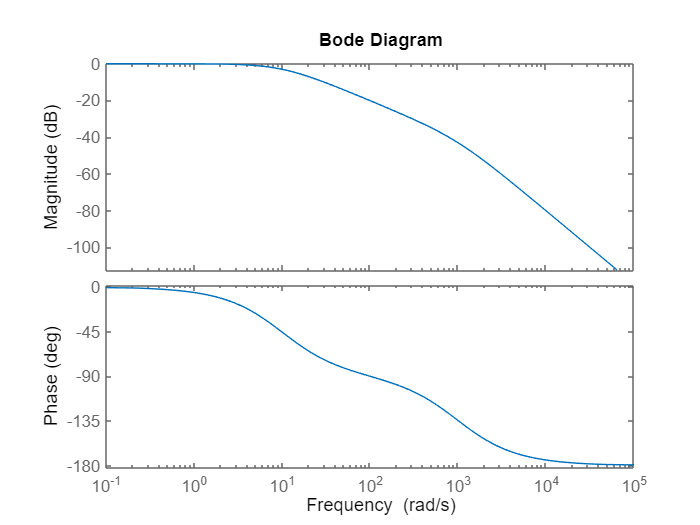

bode(G12)

Clearly, the two responses get added together.  Why do you think this is?

## Real LHP Zeros

From these plots we should be starting to develop an understanding of how a Left Half Plane (LHP) pole impacts frequency response.  Note that we don't care about RHP poles as they indicate the system is unstable meaning that the frequncy response isn't much use to us. 

We also need to understand what happens with a LHP zero:

wo = 100;
H1 = s/wo + 1

H1 =
 
  s + 100
  -------
    100
 
Continuous-time transfer function.



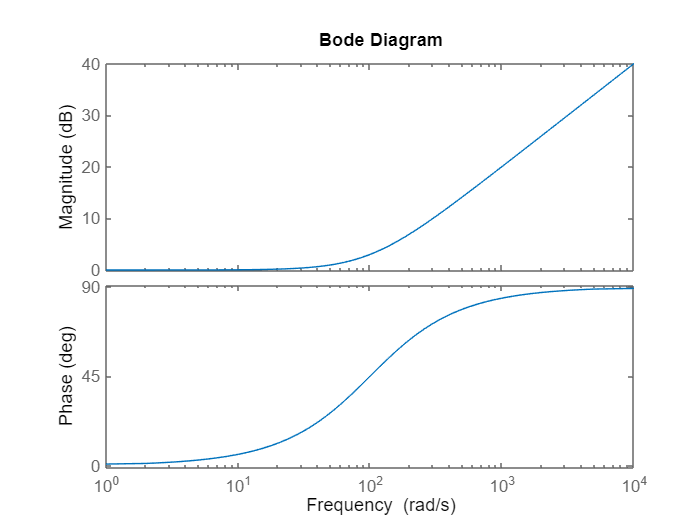

bode(H1)

How does this relate to the equivalent LHP pole? **(The impact of RHP zeros will be discussed in next week's lecture.)**

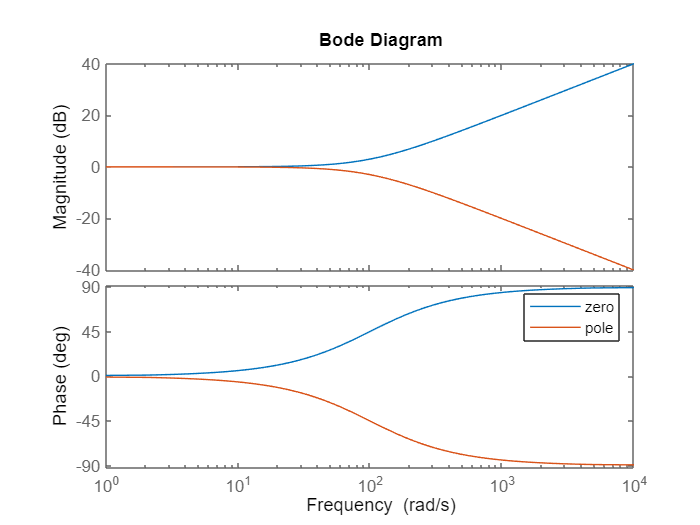

bode(H1, 1/H1)
legend("zero","pole")

Why do you think this is?

What happens to the frequency response when we cascade the zero with the two poles we made earlier?

Gbig = G1 * G2 * H1

Gbig =
 
       10000 s + 1e06
  -------------------------
  100 s^2 + 101000 s + 1e06
 
Continuous-time transfer function.



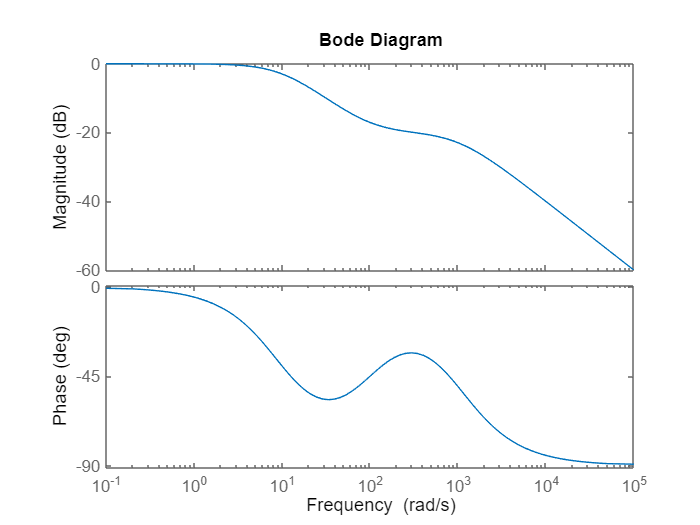

bode(Gbig)

## Gain

Up to this point we have worked with systems with unity gain.  What happens if this is not the case?

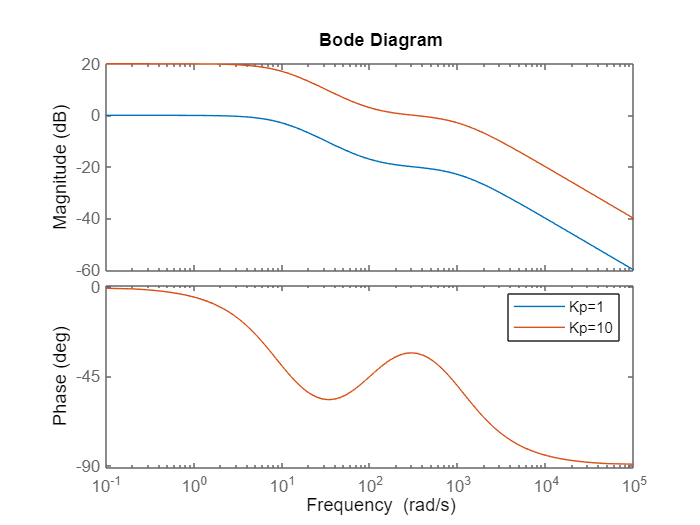

Kp = 10;
bode(Gbig, Kp*Gbig)
legend("Kp=1", strcat("Kp=",num2str(Kp)));

What happens if the gain is less than zero?

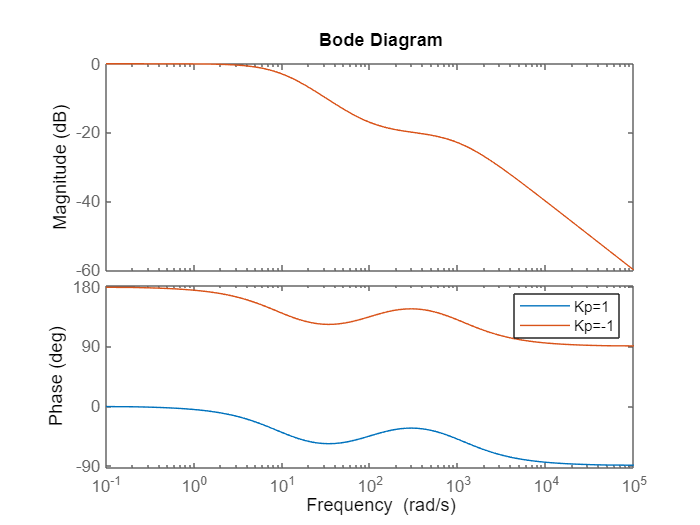

Kp = -1;
bode(Gbig, Kp*Gbig)
legend("Kp=1", strcat("Kp=",num2str(Kp)));

## Example application

At this point, you've seen how the following building blocks can be brought together to build a frequency response:

- LHP poles

- LHP zeros

- gain

It is fair to assume that you black boxes have been built using these building blocks.  

There are however other building blocks that can be encoutered.  Consider the system from the MTHE 393 Project Kickoff Lecture:

plant = 10 / (s^2 + 0.5*s + 5)

plant =
 
        10
  ---------------
  s^2 + 0.5 s + 5
 
Continuous-time transfer function.



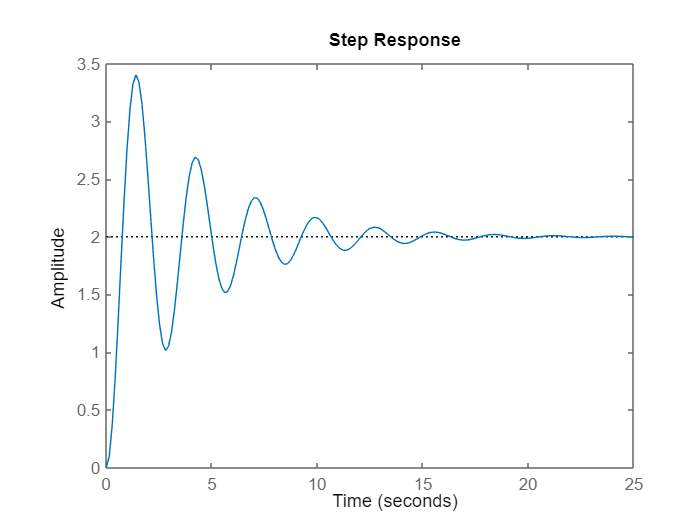

step(plant)

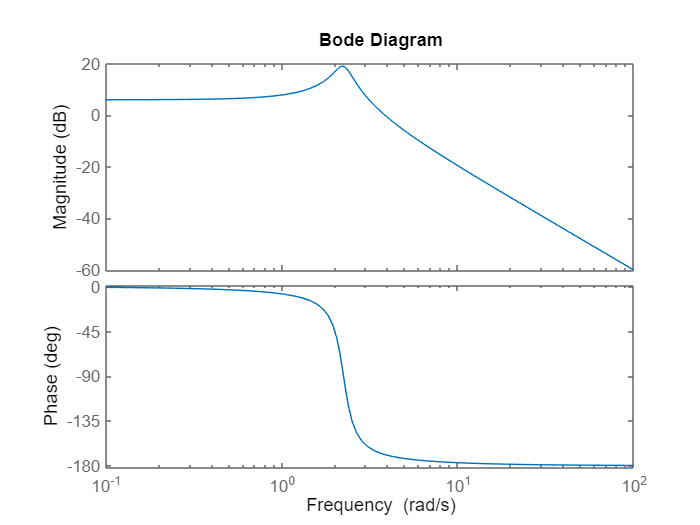

bode(plant)

This plant has complex poles

pole(plant)

ans =   -0.2500 + 2.2220i
  -0.2500 - 2.2220i


You often see these dynamics in when studying the vibration of mechanical systems, i.e., 

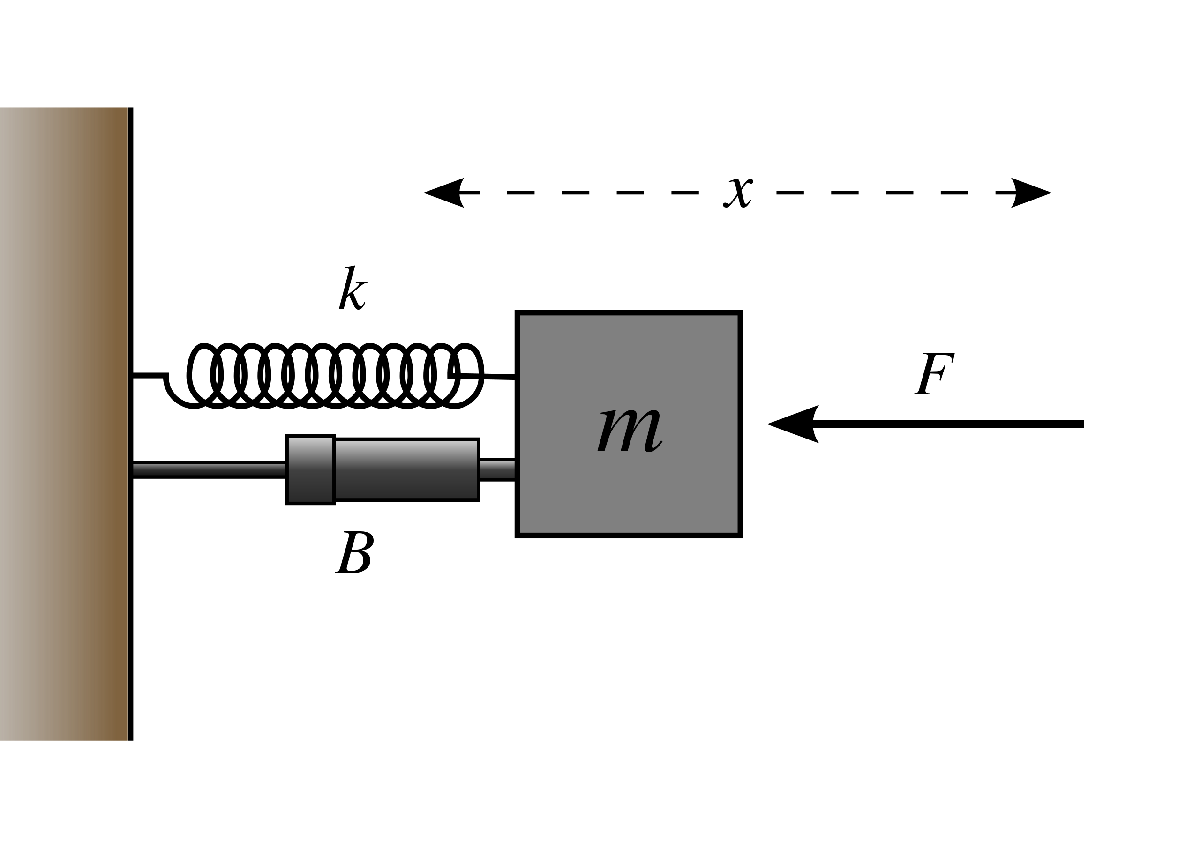

the end...